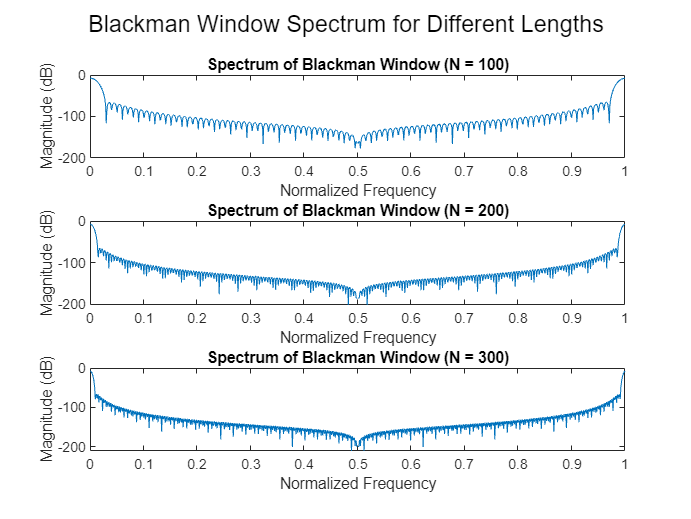

N_values = [100, 200, 300];
DFT_size = 1024;
frequencies = linspace(0, 1, DFT_size);
figure;

for i = 1:length(N_values)
    N = N_values(i);
    window = blackman(N);
    window_padded = [window; zeros(DFT_size - N, 1)];
    window_spectrum = fft(window_padded);
    window_spectrum_magnitude = abs(window_spectrum) / N;
    subplot(length(N_values), 1, i);
    plot(frequencies, 20 * log10(window_spectrum_magnitude));
    title(['Spectrum of Blackman Window (N = ', num2str(N), ')']);
    xlabel('Normalized Frequency');
    ylabel('Magnitude (dB)');
    xlim([0, 1]);
end

sgtitle('Blackman Window Spectrum for Different Lengths');

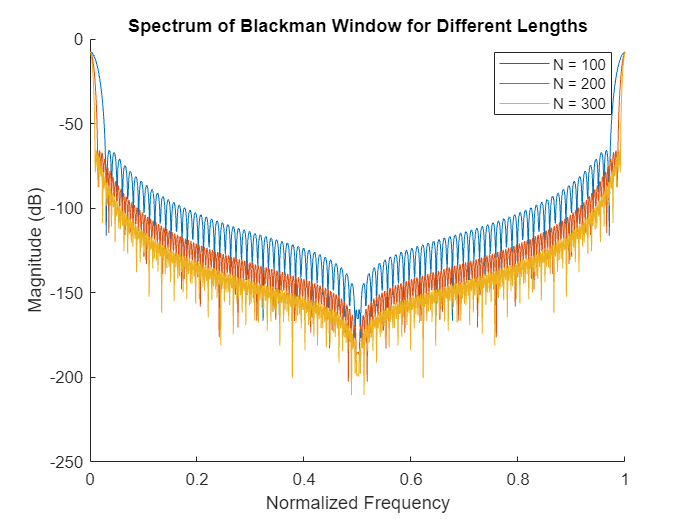


figure;
hold on;
for i = 1:length(N_values)
    N = N_values(i);
    window = blackman(N);
    window_padded = [window; zeros(DFT_size - N, 1)];
    window_spectrum = fft(window_padded);
    window_spectrum_magnitude = abs(window_spectrum) / N;
    plot(frequencies, 20 * log10(window_spectrum_magnitude), 'DisplayName', ['N = ', num2str(N)]);
end

hold off;

title('Spectrum of Blackman Window for Different Lengths');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
xlim([0, 1]);
legend;